## Building a FEM tool from scratch

April 2020, David Braun TUM  

The **Finite Element Method** (FEM) is the most common modeling and simulation technique for both 2D and 3D solid bodies. It is a **numerical method** for solving complex problems within mathematical physics and engineering.

Real world problems are usually too complex to be solved analytically. FEM provides an **approximate solution to partial differential equations** by subdividing large systems into smaller, simpler parts that are called finite elements. 

Ultimately, the finite element method formulation of a boundary value problem will result in a system of algebraic equations, that can be solved by simple system of linear equations.

         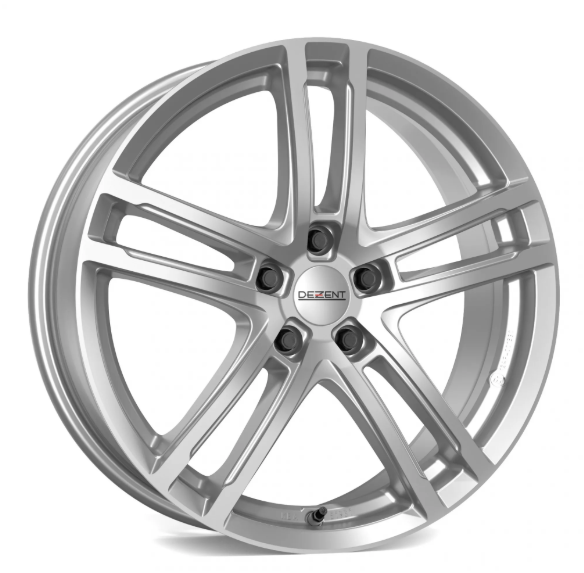                                                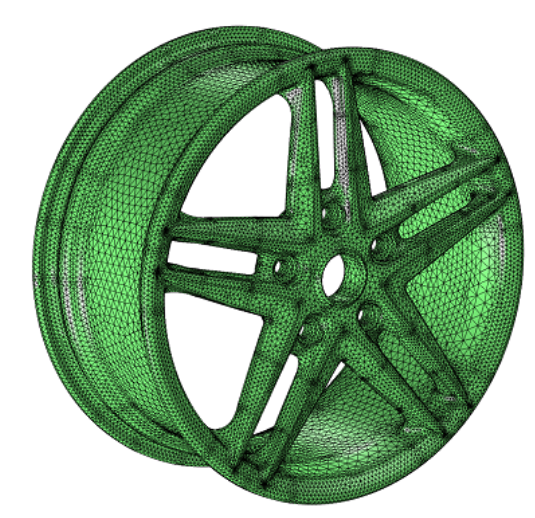

Now, without further ado, let us build a simple FEM application from scratch using MATLAB!

## What should our tool do?

Although some of us are true **TUM rocket scientists**, we want to keep it simple. Hence we will consider an example, many of us are familiar with: a clamped beam.

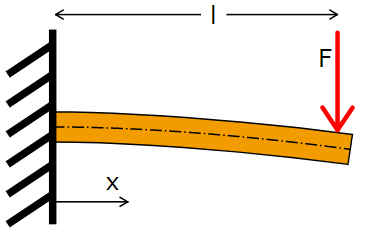

Lets start by analyzing a **clamped beam** in two dimensions. We are interested in the deformation, strain and stress distribution which results after applying a point force F at the tip. 

#### How do we tackle this problem using FEM?

Before continouing onwards, I would like to clearify that an elaborate discussion of FEM would clearly exceed the scope of this project. Interested students are referred to the **lecture "FEM" of Prof. Wall** ([http://www.lnm.mw.tum.de](http://www.lnm.mw.tum.de)), where a detailed introduction to the finite element method is provided. Nevertheless, I am trying my best to provide a general understanding of the concept. 

First of all we have to model our beam. Although our example appears not to be overly complicated, typical problems in structural mechanics typically posses a geometry far to complex to be solved analytically! That's why we break down the geometry into many little subdomains called **finite elements**. From there we will be using simple shape functions to describe the displacement of each of our finite elements. Considering each element at a time, we will be able to compute an elementwise stiffness matrix ${\mathit{\mathbf{k}}}^{\left(e\right)}$ and an elementwise loading vector ${\mathit{\mathbf{s}}}^{0\left(e\right)}$ by evaluating elementwise defined integrals. Thereafter, all element quantities are assembled to a global stiffness matrix $\mathit{\mathbf{K}}$ and a global load vector $\mathit{\mathbf{F}}$. Visually speaking, two neighboring elements both contribute to the same nodal displacement value. At this point we are able to directly enforce boundary conditions. In our case, we will be accounting for the support of the beam, as well as, applying the point load. 

Finally, a discrete global system of linear equations results: ***KD****=****F. ***With the help of MATLAB, we will solve for the vector ***D****=****K****\****F*****. **Now we have the solution $\mathit{\mathbf{D}}$ at hand, which consists of the nodal values of the displacement field. 

Considering potential damage, we are also interested in the resulting stress distribution. To calculate the approximated stresses we will perform a post-processing step. As always, results are only worth much if they allow for evaluation. That is, we want to visualize both, the resulting deformation and the resulting stress distribution.

## 1. (Continous) 2D-geometry

After having clearified the general FEM approach, we start of by creating a simple 2D rectangular geometry that models our beam.

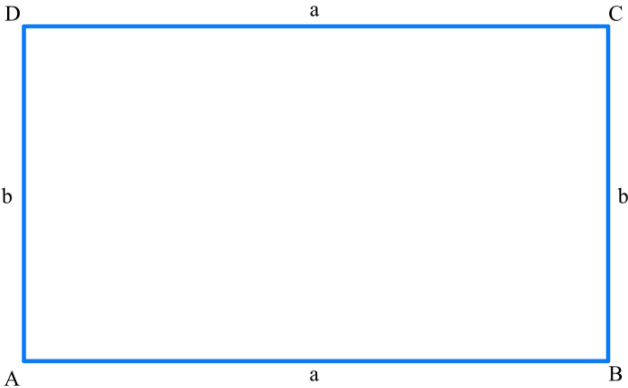

Remark that we are **not yet** concerned about any boundary conditions or support structures.

% We want to clear the workspace & the command window
clear,clc
% besides that we also close all figures.
close all

% Throughout the course of this project, we will need a lot
% of different functionalites (e.g. meshing, visualization...). 
% To keep our project modular and debugging friendly, we will be
% using purposly-created MATLAB functions to perform certain tasks.  

% This script, main.mlx, will serve as the
% entry point to our FEM tool. From here we will
% call several functions which are located in
% a subfolder called "utility".

% Let's add the utility folder to the MATLAB
% search path. Try commenting below line to unterstand 
% its purpose. 
addpath('utility');

Now let's start creating a rectangular geometry:

%    X|------------------------a----------------------|
%    X|                                               |
%    X|                                               b
%    X|                                               |
%    X|------------------------a----------------------|
%    X  <- beam clamped to the wall (we will deal with that later down the road)

a = 5; 
b = 1;

% We are also specifying the uniform thickness of our structure:
T = 1;



Let's visualize our beam in a MATLAB plot!

In order to keep our main program clean, we outsource this task to a newly created function, called "visualizegeometry.m". For reasons of good practice, we try to make our code as easy to understand as possible.

This not only helps other people that try to figure out what we have done, but will also allow us to modify code comfortably at a later stage.

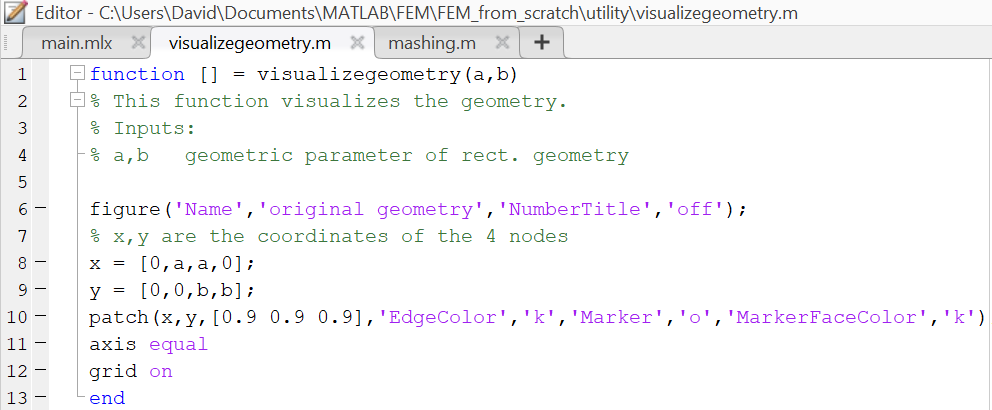

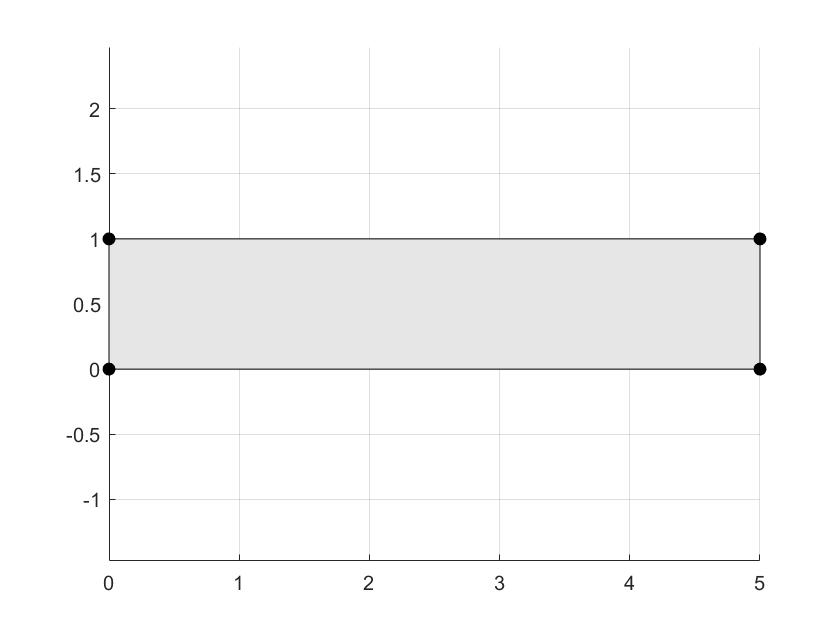

% Note how we call the helper function visualizegeometry.m
% located in the utility folder using a,b as input.
visualizegeometry(a,b)


% If you want to find out what one of your functions does, simply prompt 
% "doc visualizegeometry" into the command line.

The starting point for the FE concept is given by the **weak** **form **of the governing differential equations of linear-elastic continuum mechanics. 

 

Interested students are referred to **Prof. Wall's lecture "FEM"** for a detailed derivation of above weak form. For the time beeing, let's consider this system of partially differentiable equations as given. 

Given complex geometries $\Omega$ (that is basically any geometry of interest), solving for an analytical solution $\mathit{\mathbf{u}}$ ($\mathit{\mathbf{u}}$ = displacement field) is very hard. Instead we try to find an approximate solution ${\mathit{\mathbf{u}}}_h$ by transforming the continous problem into a discrete problem. 

## 2. Discretization

We start of by partitioning our global geometry $\Omega$ into *numele* subdomains $\Omega^e$, called finite elements. Typically these elements are cubical or tetrahedral in 3D or rectangular or triangular in 2D. Throughout the following, we will be using 2D-bilinear rectangular elements. The starting- and endpoint, or more general the edges of an element, are denoted as nodes. 

Below, I have visually demonstrated the concept of geometry discretization or "meshing" using 2D-bilinear rectangular elements on our beloved beam.

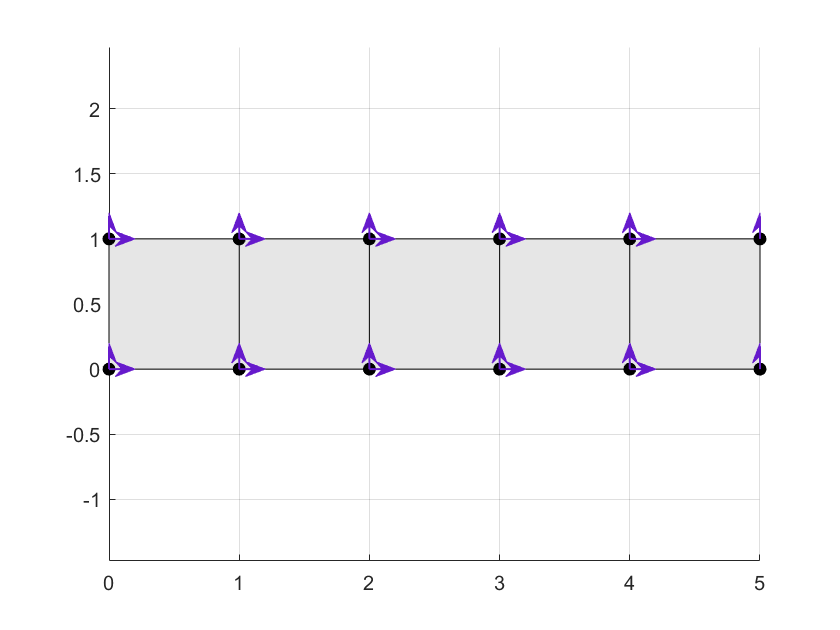

The position (and deformation) of each individual element can be described using the nodal position  ${\bar{\mathit{\mathbf{x}}} }^{\left(e\right)}$, given in global coordinates x,y. In order to have the possibility to define functions in a local coordinate system in the same way for each element, we introduce a local parameter space $\xi \;\epsilon \;\left\lbrack -1,1\right\rbrack$ on each element.   

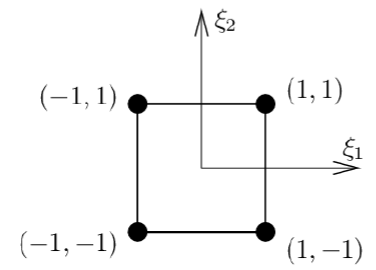

Let us define the node at the bottom left (-1,-1) as node 1. All the remaining nodes are labeled anti-clockwise. 

Now, we define four 2D-bilinear shape functions $N^i \left(\xi_1 ,\xi_2 \right)$, each taking on the value 1 at the corresponding node *i* and taking on the value 0 at all other nodes. 

Let us take some time to get familiar with this concept. Consider the shape function $N^1$. According to its definition, it is taking the value 1 at the node 1 (for justification, try inserting [-1,-1] into $N^1$) and 0 at all other nodes. This is visualized below:

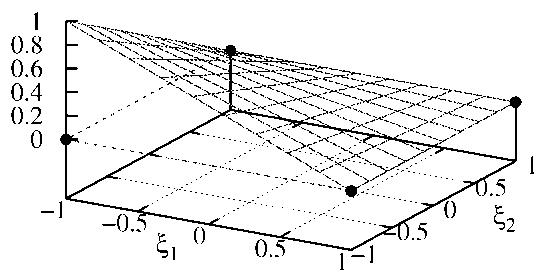

The same concept applies to $N^2$:

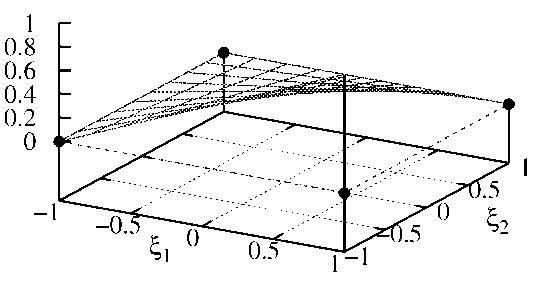

Above images have been taken from Prof. Wall's lecture script "FEM".

The introduction of shape functions allows us to approximate the geometry ${\mathit{\mathbf{x}}}^{\left(e\right)}$ by defining

${{\mathit{\mathbf{x}}}^{\left(e\right)} }_{\mathit{\mathbf{h}}} \left(\xi_1 ,\xi_2 \right)=\mathit{\mathbf{N}}\left(\xi_1 ,\xi_2 \right)\;{\bar{\mathit{\mathbf{x}}} }^{\left(e\right)}$. 

Here, the vector ${\bar{\mathit{\mathbf{x}}} }^{\left(e\right)} \;$holds the spatial coordinates ${\bar{x} }_i^{1,2}$of each node *i* in x and y direction.

Similarily, we approximate the elementwise displacement field ${\mathit{\mathbf{u}}}^{\left(e\right)}$ by the following expression.  

${{\mathit{\mathbf{u}}}^{\left(e\right)} }_{\mathit{\mathbf{h}}} \left(\xi_1 ,\xi_2 \right)=\mathit{\mathbf{N}}\left(\xi_1 ,\xi_2 \right)\;{\;\mathit{\mathbf{d}}}^{\left(e\right)}$, or 

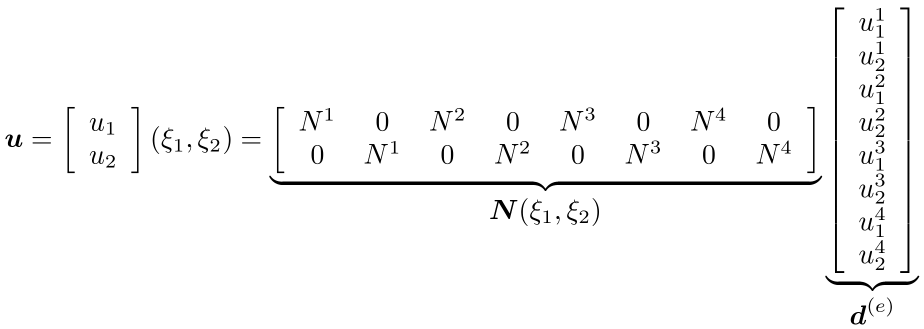.

Note that, the vector of nodal displacements${\;\mathit{\mathbf{d}}}^{\left(e\right)}$is part of the solution and yet to be determined!  

#### For the time being, that's enough theoretical input. Let's start to code a simple meshing algorithm.

% First of all we set the element size h of the rectangular elements.
% To make it even more simple, we will be using quadratic elements.
h_rel = 1;            % h_rel scales h compared to a&b   
h = h_rel*min(a,b);   

% Let's specify our material properties using a structure array.
mat = struct('name', 'Hooke', ...
             'emod', 10.e6, ...
             'poisson', 0.0);
         
% mat = struct('name', 'Hooke', ...
%              'emod', 1, ...
%              'poisson', 0.0);

% Let's specify our loads using a structure array.
Fg_vol = (9.81);
load = struct('volume',[0; -Fg_vol],...
              'traction',[0;0]);
% As we are interested in a clamped beam subject to a point force, we do
% not need any traction stresses. Nevertheless, we want to consider
% gravity. (which is modeled as a body or volume force)

% Finally, we set up a structure array holding all necessary inputs.
flag = struct('type', '2D-bilinear',  'thickness', T,  'material', mat,'numele',[],'load',load);
% Note how we can use structure arrays within structure arrays.
% The entry "numele", hence the number of finite elements, is yet to be specifed.

At this point everything is set for the discretization. Once again we are using a newly created function "meshing.m" to do the heavy-lifting.

Mashed the geometry into 5 elements.

[Xbar,EDOF,GDOF,flag] = mashing(h,a,b,flag);  


% The function takes the element size h and the geometric parameters a and b
% as input. Besides that, we also give the structured array. 

% [Xbar,EDOF,GDOF,flag] are the functions outputs.
Xbar

Xbar =      0     1     2     3     4
     0     0     0     0     0
     1     2     3     4     5
     0     0     0     0     0
     1     2     3     4     5
     1     1     1     1     1
     0     1     2     3     4
     1     1     1     1     1


% Xbar holds the absolut position of each node. [#of element-nodes,numele] = size(Xbar)

% NODE NUMBERING:
%     --------a-------
%     | . ...        |
%     | .            |
%     b . ...        b
%     | 4-3 8-7      |
%     | 1-2 5-6 ...  |
%     --------a-------

EDOF,GDOF

EDOF =      1     9    17    25    33
     2    10    18    26    34
     3    11    19    27    35
     4    12    20    28    36
     5    13    21    29    37
     6    14    22    30    38
     7    15    23    31    39
     8    16    24    32    40


GDOF =      1     3     9    13    17
     2     4    10    14    18
     3     9    13    17    21
     4    10    14    18    22
     5    11    15    19    23
     6    12    16    20    24
     7     5    11    15    19
     8     6    12    16    20


% EDOF and GDOF are the elemental/global degrees of freedom. 
% GDOF, hence the global DOF of the structure will be essential 
% for the later assembly!

% The structured array "flag" is returned as an output because we will be
% updating it within the function. (We will assign the number of elements "numele")

At this point the geometry has been meshed and we are set to proceed with the computation of the elementwise stiffness matrix ${\mathit{\mathbf{k}}}^{\left(e\right)}$and load vector${\mathit{\mathbf{s}}}^{0\left(e\right)}$.

## 3. Elementwise computation of stiffness matrix ${\mathit{\mathbf{k}}}^{\left(e\right)}$ and load vector ${\mathit{\mathbf{s}}}^{0\left(e\right)}$

After having discretized the global geometry into *numele* finite elements, the following discrete and elementwise formulation of the weak form results.

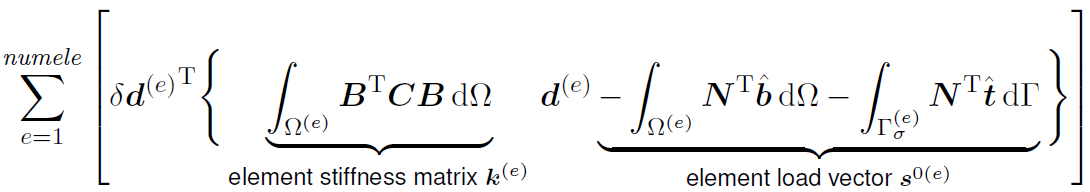

In essence, we replaced the integral over the whole domain $\Omega$ with the sum of integrals over all *numele* individual elements $\Omega^e$. As a result, we are dealing with a finite set of (*numele*) equations. In order to calculate the element stiffness matrix ${\mathit{\mathbf{k}}}^{\left(e\right)}$, we have a closer look at the following integral:

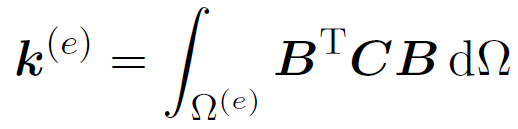

Let's take a moment and try to get familiar with above expression.

The **B**-Operator is defined as the matrix product of the linear differential operator **L** and the matrix of shape functions **N. **(We have introduced N in the previous section.)   

Considering our 2 dimensional problem at hand, the differential operator is defined as

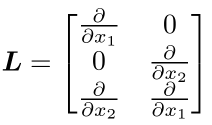

The **C**-matrix prescribes the elastic behaviour of our material. As we are dealing with a plane strain problem, the **C**-matrix is computed as follows

.

After having multiplied above matrices accordingly, we get the integrand for the element stiffness matrix ${\mathit{\mathbf{k}}}^{\left(e\right)}$.

#### **Coordinate Transformation**

Remember that all the quantities are defined as functions of the parameter space $\xi$. Consequently, we would like to do the integration in this parameter space. To this end, we perform a coordinate transformation from $\left(x,y\right)$ to$\;\left(\xi_1 ,\xi_2 \right)$, using the Jacobian determinant $\left|\mathit{\mathbf{J}}\right|$. 

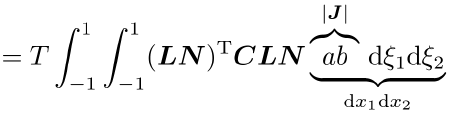 

with the Jacobian Matrix $\mathit{\mathbf{J}}$

.

**Numerical integration scheme "Gauss-Legendre quadrature"**

In praxis we almost always apply efficient numerical integration methods. Here, we will be using Gauss(-Legendre) integration.

For more reference, consult your favorite math lectures or the web: [https://en.wikipedia.org/wiki/Gaussian_quadrature](https://en.wikipedia.org/wiki/Gaussian_quadrature)

#### What about the element load vector?

The computational procedure of the element load vector follows the same steps as the element stiffness matrix. As we are primarily applying point forces, we will skip the theoretical discussion at this point. (You will see later how we apply the point forces directly...)

% As before, the actual coding has been done in several (nested) functions.
% Although not explained in detail, the computation of the load vector is fully implemented.

[k_e,s0_e] = numerical_computation(Xbar,flag);   

## 4. Assembly to global stiffness matrix *K* and global force vector *F*

In the previous section, we dealt with the evaluation of the element integrals resulting in the element stiffness matrix ${\mathit{\mathbf{k}}}^{\left(e\right)}$ and the element load vector ${\mathit{\mathbf{s}}}^{0\left(e\right)}$. Now, we deal with the assembly of the element quantities to a global stiffness matrix ***K*** and a global load vector ***F***. 

In standard FEM, the primary field (here the displacement field) is chosen continuous, meaning that elements which share a node, also share the nodal quantity (here the nodal displacement) values at that node. That being said, two neighboring elements both contribute to the same nodal displacement value.

[K,F] = assembly(k_e,s0_e,Xbar,GDOF);
% The function provides the following quantities as output:
%   K - global stiffness matrix of our (discretized) structure
%   F - global load vector of our (discretized) structure

## 5. Apply Dirichlet boundary conditions & external point loads

At this point we are finally considering our boundary conditions. 

% Recalling our used node numbering scheme:
% exemplary for a=5 and b=1:
% 
%     X----a=5-----...  
%     X| 4-3  8-7  
%     X| 1-2  5-6 ...
%     X----a=5-----...


% According to above scheme, we have to "lock" both DOF of node 1 and 4 to model the fixed
% support. That is, DOF [1,2,7,8] are fixed.

DBC = [1,2,7,8]';    % DBC consists of all fixed DOF

Now the last remaining task is to apply the point force to our beam. As you see this can be done in a straight forward manner:

ext_force = [22, -10000;...
             24, -10000];
% first column: direction/DOF 
% second column: magnitude

% Manipulate force vector
F(ext_force(:,1)) = F(ext_force(:,1)) + ext_force(:,2);

Once we have specified the fixed DOF (due to the wall support) and the DOF where we apply our force, we can introduce both boundary conditions to the system.

[K_red,F_red] = enforceDBC(K,F,DBC);       
% The approach is clear. All DOF where a deflection
% is prescribed are excluded from the system.

## 6. Solve linear system of equations for the discrete displacement vector $\mathit{\mathbf{D}}$

Finally we arrive at the linear system of equations $\mathit{\mathbf{KD}}=\mathit{\mathbf{F}}$.

As far as the stiffness matrix $\mathit{\mathbf{K}}$ is invertible (which it is almost always), the solution of the discrete displacement vector $\mathit{\mathbf{D}}$ is easily obtained by $\mathit{\mathbf{D}}=\mathit{\mathbf{K}}\backslash \mathit{\mathbf{F}}$.

D = solveFEM(K_red,F_red,DBC);

## 7. Post-processing: computing stresses & strains resulting from  deflection ${\mathit{\mathbf{u}}}_{\mathit{\mathbf{h}}}$

Now, haveing the solution $\mathit{\mathbf{D}}$ at hand, consisting of the nodal values for the displacement field, we are also interested in the resulting stresses. To calculate the approximated stresses we will perform a post-processing step. 

Recalling that the determine the approximated deformation ${\mathit{\mathbf{u}}}_h^{\left(e\right)}$ from the solution ${\mathit{\mathbf{d}}}^{\left(e\right)}$ via ${\mathit{\mathbf{u}}}_h^{\left(e\right)}$= **N**${\;\mathit{\mathbf{d}}}^{\left(e\right)}$,

- $\varepsilon_h^{\left(e\right)} ={\mathbf{Lu}}_h^{\left(e\right)} =\mathit{\mathbf{B}}{\mathit{\mathbf{d}}}^{\left(e\right)}$        , gives us the nodal strains.

- $\sigma_h^{\left(e\right)} =\mathit{\mathbf{C}}\varepsilon_h^{\left(e\right)} ={\mathbf{CBd}}^{\left(e\right)}$     , gives us the nodal stresses.

[stresses,strains,dbar_e] = postprocessing(Xbar,D,GDOF,flag);

## 8. Visualize results

Last but not least, let us quickly visualize the outcome of our simulation. Besides the resulting deformation, we are also interested in the stress distribution.

Patch color indicates the local stress intensity (elementwise Van-Mises stress) with colormap: green(=low acting stresses) to red (=high acting stresses).

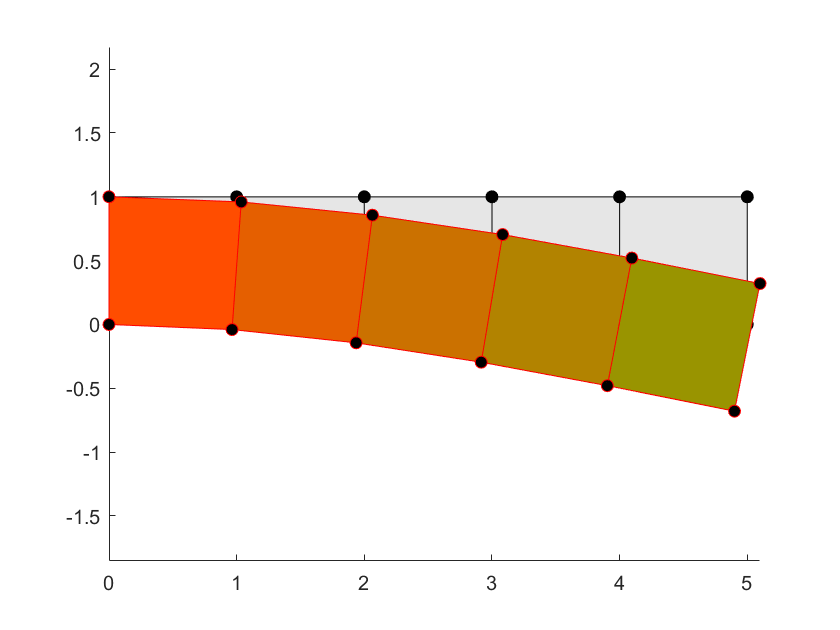

visualizeresults(Xbar,dbar_e,stresses)

## End notes

I hope you enjoyed coding your own FEM application. I think we all agree that this implementation of the FE concept is neither efficient nor particually clever. Yet it showcases the enormous potential of using MATLAB (or any other software out there) to enhance your personal studies.

From my personal experience I am convinced that projects like that elevate the personal learning experience. 

If you have any questions, doubts or feedback regarding this project, feel free to post them in the comments sections below or contact me directly via mail: [**matlab@fsmb.mw.tum.de**](javascript:linkTo_UnCryptMailto('nbjmup+nbumbcAgtnc\/nx\/uvn\/ef');)** .**